raw_pix_folder = "D:\programming\githubRepos\Connectome_pipe\test\pixel";
filter_out_foler =  "D:\programming\githubRepos\Connectome_pipe\test\pixel\pixel_filtered";
raw_px_files = get_files_of_folder(raw_pix_folder);
%making filtered pixel color of middle 1/4 value
for i = 1:numel(raw_px_files)
    fpath = fullfile(raw_pix_folder, raw_px_files(i).name);
    myt = readtable(fpath);
    A = table2array(myt);
    rowSum = sum(A, 2);
    N = size(A,1);
    k = ceil(0.1 * N);
    [~, idx] = sort(rowSum, 'descend');
    topQuarterRows = A(idx(1:k), :);

    % Filter the top quarter rows and save to a new table
    filtered_t = array2table(topQuarterRows);
    filtered_t.Properties.VariableNames = myt.Properties.VariableNames;
    [~, name, extension] = fileparts(raw_px_files(i).name);
    newname = strcat(name, '_top10');

    newFilteredName = fullfile(filter_out_foler, [newname extension]);
    writetable(filtered_t, newFilteredName);
end

%make filtering for the interquantile range
for i = 1:numel(raw_px_files)
    fpath = fullfile(raw_pix_folder, raw_px_files(i).name);
    myt = readtable(fpath);
    A = table2array(myt);
    rowSum = sum(A, 2);          % N x 1

    low  = prctile(rowSum, 25);
    high = prctile(rowSum, 75);
    middleHalfRows = A(rowSum >= low & rowSum <= high, :);

    % Filter the top quarter rows and save to a new table
    filtered_t = array2table(middleHalfRows);
    filtered_t.Properties.VariableNames = myt.Properties.VariableNames;
    [~, name, extension] = fileparts(raw_px_files(i).name);
    newname = strcat(name, '_interQt');

    newFilteredName = fullfile(filter_out_foler, [newname extension]);
    writetable(filtered_t, newFilteredName);
end

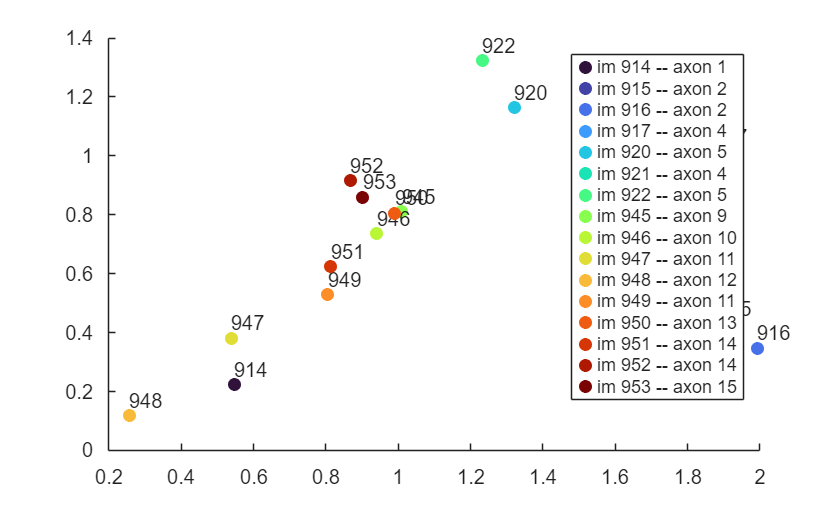

%sp = [0,0];
figure;
hold on;
mylegend = cell(numel(sum_data.image_id), 1);
colors = turbo(numel(sum_data.image_id));
%plotting c1 and c3
for i = 1:numel(sum_data.image_id)
    x = sum_data.cmass(i,1)/sum_data.cmass(i, 3);
    y = sum_data.cmass(i,2)/sum_data.cmass(i, 3);
    scatter(x, y, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :))
    text(x, y+0.05, num2str(sum_data.image_id(i)));
    %plot(x, y, 'Color', colors(i, :),'LineWidth', 1);
    q = sprintf('image_id = %d', sum_data.image_id(i));
    axon = fetch(sln_image.AxonImageAssociation & q);
    l = sprintf('im %d -- axon %d', sum_data.image_id(i), axon.axon_id);
    mylegend{i} =l;
end
legend(mylegend);